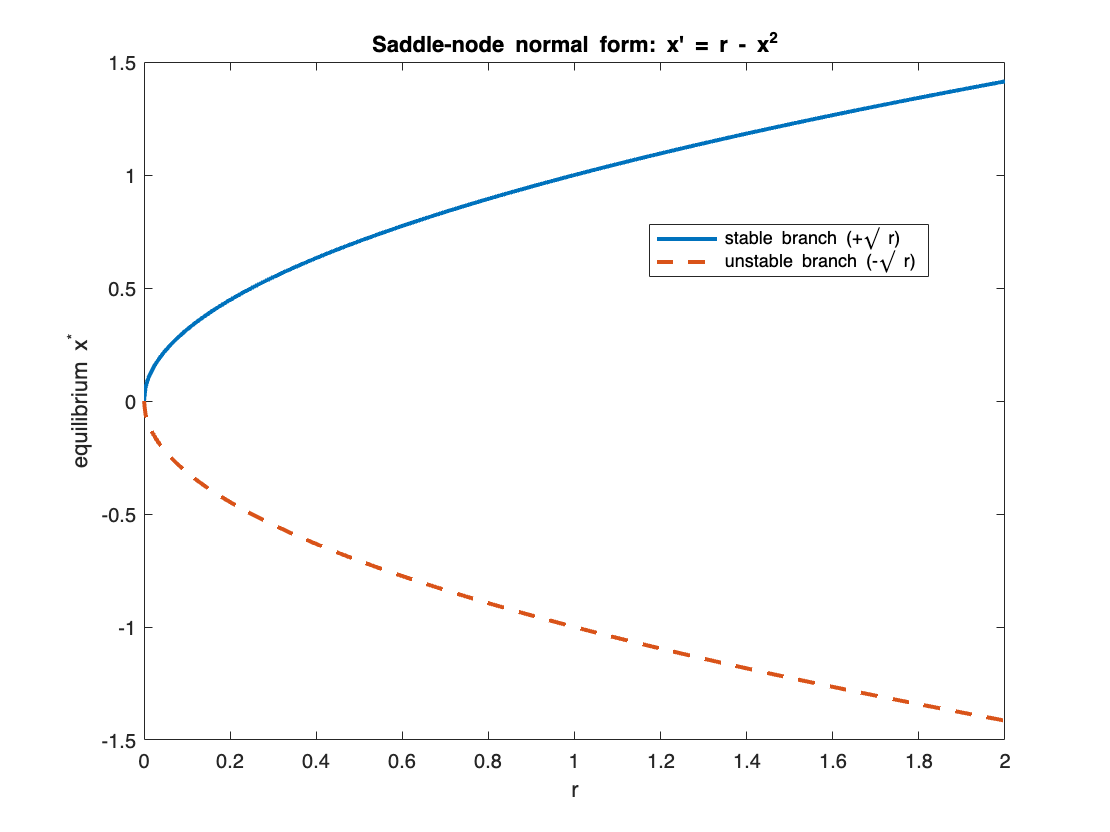

%% ================================================================
%  2) Normal-form bifurcations: saddle-node, transcritical, pitchfork
% ================================================================

% Define parameter range
r = linspace(-2,2,1201);

% --- (a) Saddle-node: x' = r - x^2 ---
% equilibria for r>=0: x = +/- sqrt(r)
r_sn = r(r>=0);
x_sn1 =  sqrt(r_sn);
x_sn2 = -sqrt(r_sn);
% stability: f_x = -2x => stable if x>0, unstable if x<0

figure('Name','Normal forms: saddle-node','Color','w'); hold on; box on;
plot(r_sn, x_sn1,'LineWidth',2);         % stable
plot(r_sn, x_sn2,'--','LineWidth',2);    % unstable
xlabel('r'); ylabel('equilibrium x^*');
title('Saddle-node normal form: x'' = r - x^2');
legend('stable branch (+\surd r)','unstable branch (-\surd r)','Location','best');

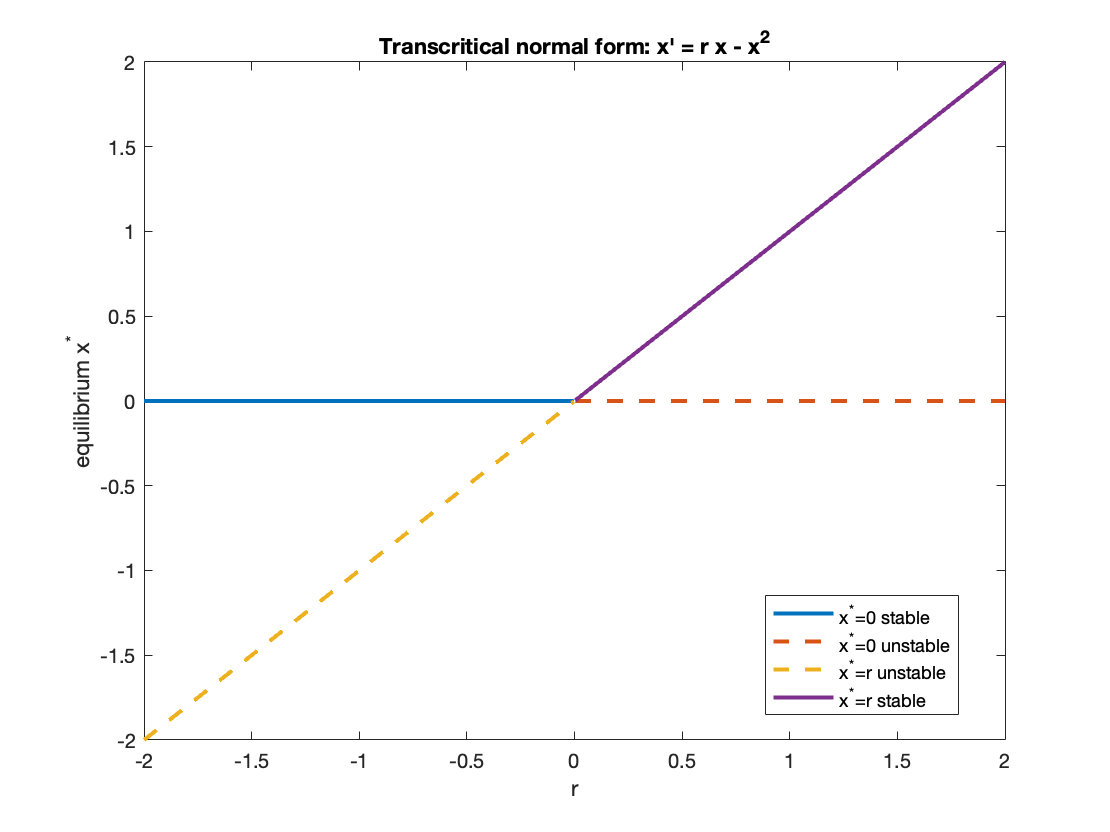


% --- (b) Transcritical: x' = r x - x^2 = x(r-x) ---
% equilibria: x=0 and x=r
x_tc0 = zeros(size(r));
x_tcr = r;
% stability: f_x = r - 2x
%  at x=0: f_x=r => stable if r<0
%  at x=r: f_x = r - 2r = -r => stable if r>0

figure('Name','Normal forms: transcritical','Color','w'); hold on; box on;
plot(r(r<0), x_tc0(r<0),'LineWidth',2);           % stable part of x=0
plot(r(r>0), x_tc0(r>0),'--','LineWidth',2);      % unstable part
plot(r(r<0), x_tcr(r<0),'--','LineWidth',2);      % unstable part of x=r
plot(r(r>0), x_tcr(r>0),'LineWidth',2);           % stable part
xlabel('r'); ylabel('equilibrium x^*');
title('Transcritical normal form: x'' = r x - x^2');
legend('x^*=0 stable','x^*=0 unstable','x^*=r unstable','x^*=r stable','Location','best');

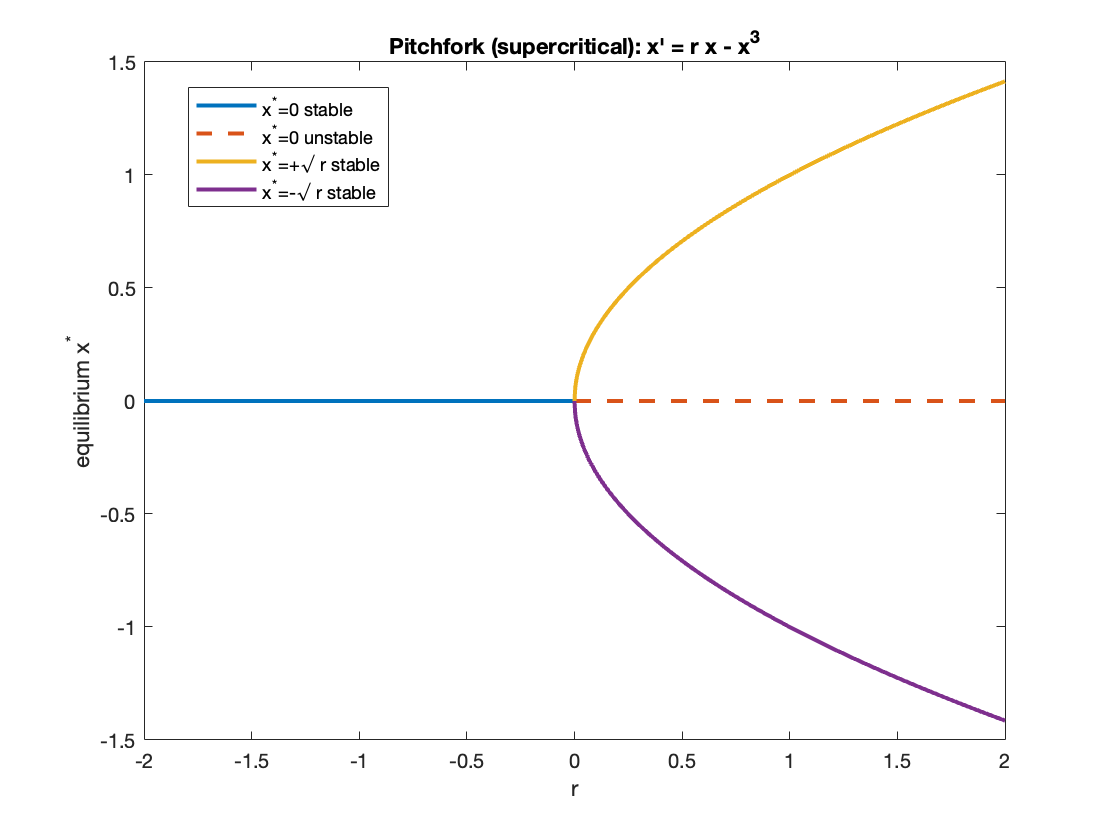


% --- (c) Pitchfork (supercritical): x' = r x - x^3 = x(r-x^2) ---
% equilibria: x=0 for all r; x=±sqrt(r) for r>=0
r_pf = r(r>=0);
x_pf0 = zeros(size(r));
x_pf1 =  sqrt(r_pf);
x_pf2 = -sqrt(r_pf);
% stability: f_x = r - 3x^2
%  at x=0: stable if r<0
%  at x=±sqrt(r): f_x = r - 3r = -2r <0 for r>0 => stable

figure('Name','Normal forms: pitchfork (supercritical)','Color','w'); hold on; box on;
plot(r(r<0), x_pf0(r<0),'LineWidth',2);      % stable x=0 for r<0
plot(r(r>0), x_pf0(r>0),'--','LineWidth',2); % unstable x=0 for r>0
plot(r_pf, x_pf1,'LineWidth',2);            % stable
plot(r_pf, x_pf2,'LineWidth',2);            % stable
xlabel('r'); ylabel('equilibrium x^*');
title('Pitchfork (supercritical): x'' = r x - x^3');
legend('x^*=0 stable','x^*=0 unstable','x^*=+\surd r stable','x^*=-\surd r stable','Location','best');